# AAE340 HW#4

## <1b> & <1c>

Numerically integrate


$$\overset{\cdot \cdot }{x} +2\zeta \omega_n \overset{\cdot }{x} +{\omega_n }^2 x=\frac{f_o }{m}\mathrm{cos}\left(\omega t\right)$$


% Solving with ode45
zeta = 1/8; % Setting the zeta variable
omega_n = 1; % Setting the omega variable
f_over_m = 1; % Setting the f over m variable


## CASE 1: omega = 0

omega = 0;
tspan = [0 10*2*pi/omega_n]; % Defining the interval of t
x0 = [0 0]; % Defining the initial conditions 
[t, x] = ode45(@(t,x) fcn(t,x,zeta,omega_n,f_over_m,omega), tspan, x0); 
% Solving the ode with ode45
x0_numer = x(:,1); % Assigning the x_numerical values to a variable
f_t = f_over_m * cos(omega .* t);

Plotting the result of the solve differential equation 

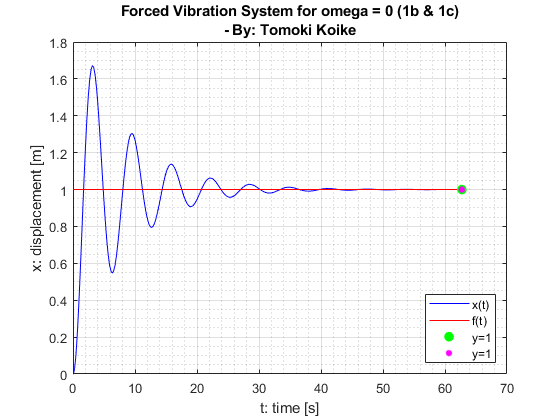

figure(1)
plot(t, x0_numer, '-b')
ylabel('x: displacement [m]')
xlabel('t: time [s]')
title({'Forced Vibration System for omega = 0 (1b & 1c)','- By: Tomoki Koike'})
grid on
grid minor
box on 
hold on 
plot(t, f_t, '-r')
plot(62.7214, 1, '.g','MarkerSize',25)
plot(62.7214, 1, '.m','MarkerSize',15)
hold off
legend('x(t)', 'f(t)', 'y=1', 'y=1', 'Location','southeast')

## CASE 2: omega = 0.5

omega = 0.5;
tspan = [0 10*2*pi/omega_n]; % Defining the interval of t
x0 = [0 0]; % Defining the initial conditions 
[t, x] = ode45(@(t,x) fcn(t,x,zeta,omega_n,f_over_m,omega), tspan, x0); 
% Solving the ode with ode45
x05_numer = x(:,1); % Assigning the x_numerical values to a variable
f_t = f_over_m * cos(omega .* t);

Plotting the result of the solve differential equation 

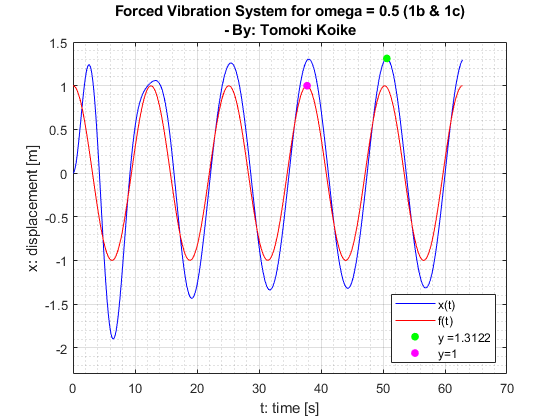

figure(1)
plot(t, x05_numer, '-b')
ylabel('x: displacement [m]')
xlabel('t: time [s]')
title({'Forced Vibration System for omega = 0.5 (1b & 1c)','- By: Tomoki Koike'})
grid on
grid minor
box on 
ylim([-2.3 1.5])
hold on 
plot(t, f_t, '-r')
plot(50.6157, 1.3122, '.g','MarkerSize',20)
plot(37.7581, 1, '.m','MarkerSize',20)
hold off
legend('x(t)', 'f(t)', 'y =1.3122', 'y=1', 'Location','southeast')

## CASE 3: omega = 1.0

omega = 1.0;
tspan = [0 10*2*pi/omega_n]; % Defining the interval of t
x0 = [0 0]; % Defining the initial conditions 
[t, x] = ode45(@(t,x) fcn(t,x,zeta,omega_n,f_over_m,omega), tspan, x0); 
% Solving the ode with ode45
x10_numer = x(:,1); % Assigning the x_numerical values to a variable
f_t = f_over_m * cos(omega .* t);

Plotting the result of the solve differential equation 

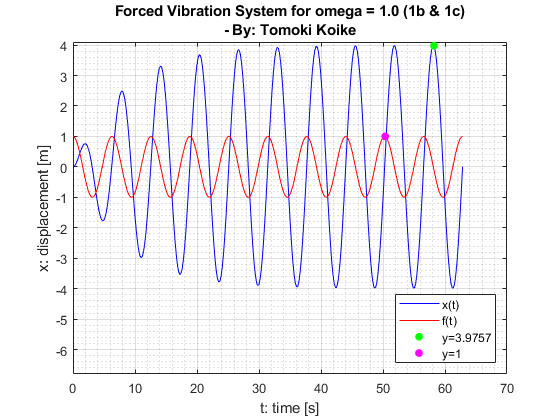

figure(1)
plot(t, x10_numer, '-b')
ylabel('x: displacement [m]')
xlabel('t: time [s]')
title({'Forced Vibration System for omega = 1.0 (1b & 1c)','- By: Tomoki Koike'})
grid on
grid minor
box on 
ylim([-6.8 4.1])
hold on 
plot(t, f_t, '-r')
plot(58.2175, 3.9757, '.g','MarkerSize',20)
plot(50.3516, 1, '.m','MarkerSize',20)
hold off
legend('x(t)', 'f(t)', 'y=3.9757', 'y=1','Location','southeast')

## CASE 4: omega = 1.5

omega = 1.5;
tspan = [0 10*2*pi/omega_n]; % Defining the interval of t
x0 = [0 0]; % Defining the initial conditions 
[t, x] = ode45(@(t,x) fcn(t,x,zeta,omega_n,f_over_m,omega), tspan, x0); 
% Solving the ode with ode45
x15_numer = x(:,1); % Assigning the x_numerical values to a variable
f_t = f_over_m * cos(omega .* t);

Plotting the result of the solve differential equation 

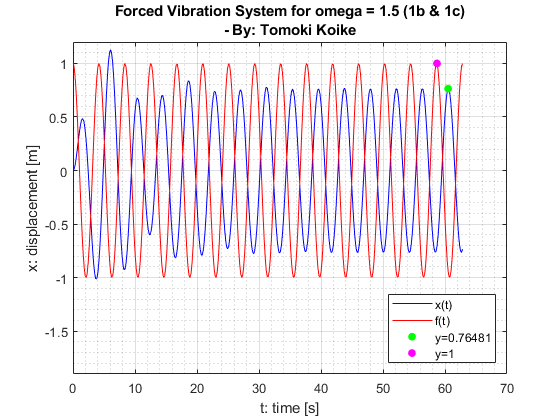

figure(1)
plot(t, x15_numer, '-b')
ylabel('x: displacement [m]')
xlabel('t: time [s]')
title({'Forced Vibration System for omega = 1.5 (1b & 1c)','- By: Tomoki Koike'})
grid on
grid minor
box on
ylim([-1.9 1.2])
hold on 
plot(t, f_t, '-r')
plot(60.5038, 0.76481, '.g','MarkerSize',20)
plot(58.7128, 1, '.m','MarkerSize',20)
hold off
legend('x(t)', 'f(t)', 'y=0.76481', 'y=1','Location','southeast')

## CASE 5: omega = 2.0

omega = 2.0;
tspan = [0 10*2*pi/omega_n]; % Defining the interval of t
x0 = [0 0]; % Defining the initial conditions 
[t, x] = ode45(@(t,x) fcn(t,x,zeta,omega_n,f_over_m,omega), tspan, x0); 
% Solving the ode with ode45
x20_numer = x(:,1); % Assigning the x_numerical values to a variable
f_t = f_over_m * cos(omega .* t);

Plotting the result of the solve differential equation 

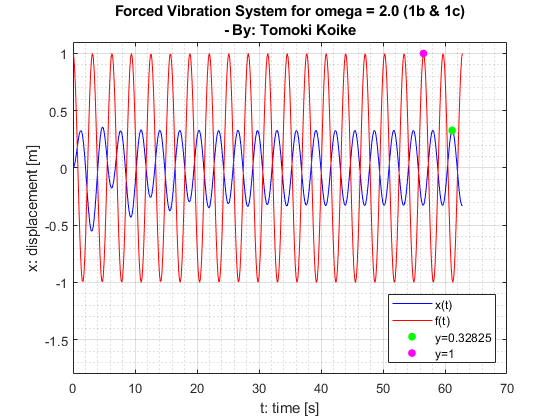

figure(1)
plot(t, x20_numer, '-b')
ylabel('x: displacement [m]')
xlabel('t: time [s]')
title({'Forced Vibration System for omega = 2.0 (1b & 1c)','- By: Tomoki Koike'})
grid on
grid minor
box on 
ylim([-1.8 1.1])
hold on 
plot(t, f_t, '-r')
plot(61.1502, 0.32825, '.g','MarkerSize',20)
plot(56.5255, 1, '.m','MarkerSize',20)
hold off
legend('x(t)', 'f(t)', 'y=0.32825', 'y=1','Location','southeast')

## <1d> & <1e>

The measurement for each cases are on the plots as green markers for x(t) amplitude and 

magenta for f/m*cos(omega*t) amplitude.

The measurements are organized as the following 

omegas = [0; 0.5; 1.0; 1.5; 2.0];
Amp_ft = [1; 1; 1; 1; 1];
Amp_xt = [1; 1.3122; 3.9757; 0.76481; 0.32825];
measured_ratios = [1; 1.3122; 3.9757; 0.76481; 0.32825];
T = table(omegas, Amp_ft, Amp_xt, ratios);
disp(T);

    omegas    Amp_ft    Amp_xt     ratios 
    ______    ______    _______    _______

       0        1             1          1
     0.5        1        1.3122     1.3122
       1        1        3.9757     3.9757
     1.5        1       0.76481    0.76481
       2        1       0.32825    0.32825



The theoretical values are the same as the AF

AF = zeros(1, 5); % Allocate the AF vector
for i = 0:4
    AF(i+1) = 1 / sqrt((1-(i*0.5/omega_n)^2)^2+(2*zeta*i*0.5/omega_n)^2);
end

Update the table to 

AF = AF';
T = table(omegas, Amp_ft, Amp_xt, measured_ratios, AF);
disp(T);

    omegas    Amp_ft    Amp_xt     measured_ratios      AF   
    ______    ______    _______    _______________    _______

       0        1             1              1              1
     0.5        1        1.3122         1.3122         1.3152
       1        1        3.9757         3.9757              4
     1.5        1       0.76481        0.76481        0.76626
       2        1       0.32825        0.32825         0.3288



AF agree with the measured values. 

## <1f>

errs = zeros(1, 5); % Allocate the error vector
for i = 1:5
    errs(i) = abs(measured_ratios(i)-AF(i))/AF(i)*100;
end

Update the tables to include the percent errors (%)

errors = errs';
T = table(omegas, Amp_ft, Amp_xt, measured_ratios, AF, errors);
disp(T);

    omegas    Amp_ft    Amp_xt     measured_ratios      AF       errors 
    ______    ______    _______    _______________    _______    _______

       0        1             1              1              1          0
     0.5        1        1.3122         1.3122         1.3152    0.22749
       1        1        3.9757         3.9757              4     0.6075
     1.5        1       0.76481        0.76481        0.76626    0.18936
       2        1       0.32825        0.32825         0.3288    0.16666



#### <ANALYSIS>

The errors are consistent in that taking 10 periods are enough to find the steady state amplitude 

for the Forced Vibration Problem so that they agree with the theoretical values. That being said, 

the very small errors are cohesive with the other results obtained.

Creating a function for the differential equation (1a)

function dxdt = fcn(t,x,zeta,omega_n,f_over_m,omega)
dxdt = zeros(2,1);  % Defining a zero vector to store the dxdt terms 
dxdt(1) = x(2); % Derivative of x1 = x2
dxdt(2) = f_over_m*cos(omega*t)-omega_n^2*x(1)-2*zeta*omega_n*x(2); 
% Derivative of x2 = -2*zeta*omega*x2
end  